# Extracting lineage information from SuperSegger

The output of SuperSegger is a set of `cell.mat` files which contain a bunch of infomration from a given cell throughout it's entire lifetime. Because I'm doing a bit of a weird experiment inwhich I only really have one fluorescence channel  being read, I don't think I can really rely on the algortithm itself extracting the integrated fluorescence information. Rather, I need to figure out how I can loop through all of these files, determine if there were daughter cells, and then broadcast the mask onto the original fluorescence image and get the intensity information. 

The benefit from this experiment is that I am really only catching (at most) one division event. This means that I don't have to do a ton of hunting through lineage trees. 

## Loading an example `.mat` file.

To begin, I'm going to load the directory of cell files from the practice segmentation round. 

% Load the example cell files. 
dataDir = '../../data/mbl_2017/images/supersegger_practice/20170628_glucose_phase/raw_im/xy3/cell/';
cellFiles = dir([dataDir 'cell*']);
cellStruct = load([dataDir cellFiles(1).name]);
length(cellFiles);

Now with everything loaded, we want to get rid of the cells that are neither born **nor** divide. This means that they were not present in the first frame and divided **at least** once.

% Separate the cell files based on division. They must divide and be born after the first time point. 
fileCounter = 0;
lineageFiles = {}


lineageFiles =

  0×0 empty cell array



for i=1:length(cellFiles)
    cellStruct = load([dataDir cellFiles(i).name]);
    disp([cellStruct.birth, cellStruct.death])
     if (cellStruct.death ==  22) && (cellStruct.birth ~=1)  % Note that the film length has been hard-coded here.    
          fileCounter = fileCounter + 1;
          lineageFiles{fileCounter} = cellFiles(i).name;
     end
end

     1     3



     1    11



     1    22



     1    22



     1    14



     1     3



     1     6



     1    22



     1    15



     1    15



     1    15



     1    22



     1    18



     1    22



     1    18



     1    19



     1    20



     1    22



     1    17



     1     1



     1     2



     1    22



     1    18



     1    22



     1    22



     1    22



     1    22



     1    15



     1    22



     4     8



     4     9



     4    22



     4    22



     7    22



     7    22



     9    14



    10    22



    12    22



    12    22



    15    22



    15    22



    16    22



    16    22



    16    18



    16    22



    16    22



    16    22



    16    19



    16    22



    18    22



    18    22



    19    22



    19    22



    19    22



    19    22



    19    22



    19    22



    20    22



    20    22



    20    22



    20    22



    20    22



    20    22



    20    22



    21    22



    21    22



    21    22



    21    22



Now we have a set of file names that mean our condition. We have to be a bit clever in how we match up sister cells. This means we will have to keep track of *who* we have already looked at. Ultimately, I would like to  keep all of these things together in a nice and cozy csv file where each row corresponds to a division event with columns indicating the daughters and their intensities. However, to get these values, I'll have to broadcast the masks of each one onto the median filtered fluorescent image. For now, let's figure out how to actually get this value from the fluorescence mask and then move forward in trying to link everything up. 

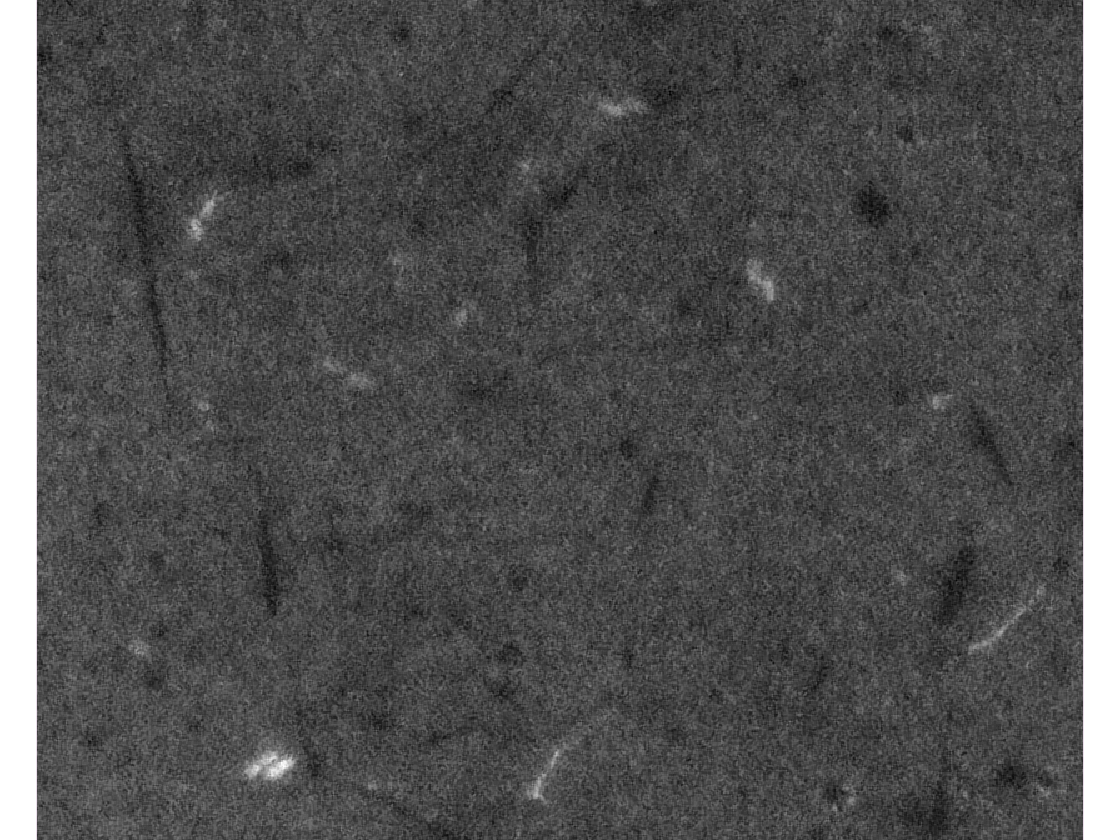

% Load the fluorescence image. 
imFluo = imread('../../data/mbl_2017/images/supersegger_practice/20170628_gluocose_mCherry/growth_movie003t22xy03c3.tif');
imshow(imFluo, [])

Now we want to take some of the cell segmentation masks and map them onto this image. 

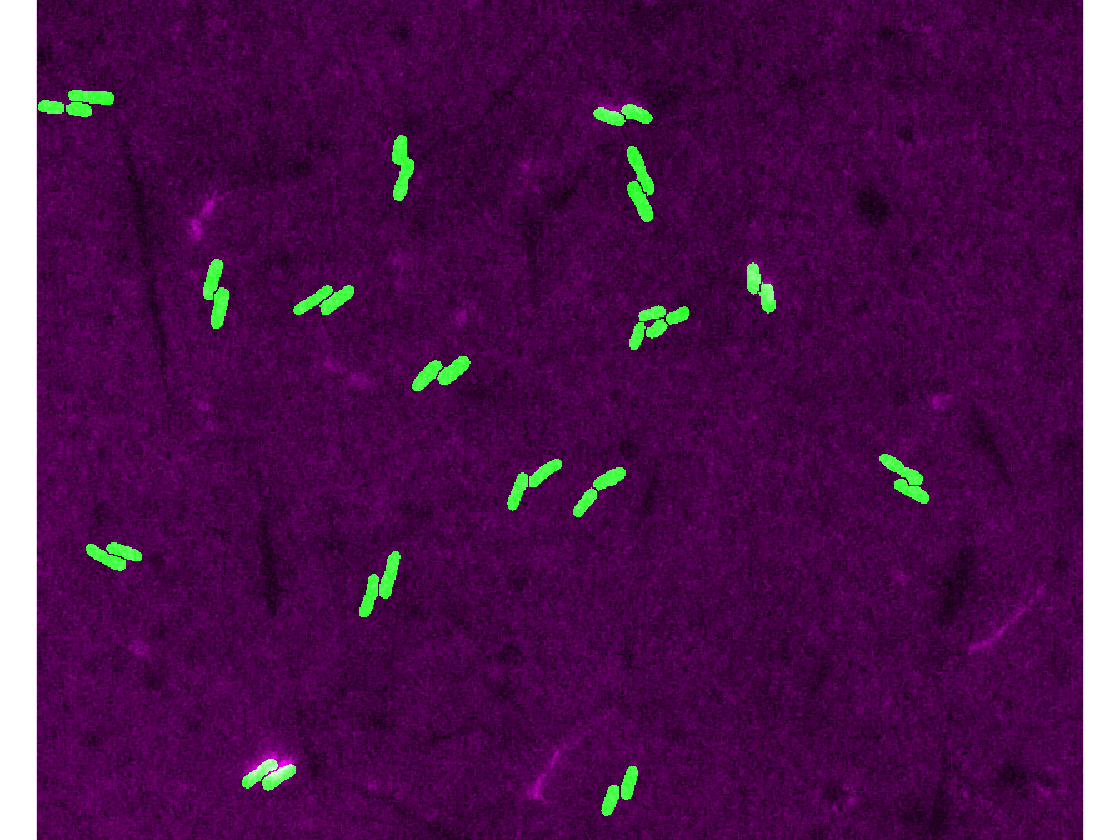

% Try to extrac the 'approved' cell masks and outline them on this image.
approvedCells = zeros(size(imFluo));
approvedCells = uint16(approvedCells);
for i=1:length(lineageFiles)
    % Load the struct and extract the cell mask. 
    cellStruct = load([dataDir lineageFiles{i}]);

    % Grab the mask and bounding box from the cellStruct.
    mask = cellStruct.CellA{end}.mask;
    xx = cellStruct.CellA{end}.xx;
    yy = cellStruct.CellA{end}.yy;
    
    % Crop the fluorescent image.
    imCrp = imFluo(yy(1):yy(end), xx(1):xx(end));
    
    % Convert the mask to that of the fluo Im
    maskTyped = uint16(mask);
    
    % Add the approved mask to the image. 
    approvedCells(yy(1):yy(end), xx(1):xx(end)) =...
            approvedCells(yy(1):yy(end), xx(1):xx(end)) + maskTyped;
        
    % Store the intensity values of each cell and the cell ID. 
    intensity(i) = sum(sum(maskTyped .* imCrp));
    cellId(i) = cellStruct.ID;
    end
imPhase = imread('../../data/mbl_2017/images/supersegger_practice/20170628_glucose_phase/raw_im/raw_im/growth_movie003t22xy03c3.tif');
imshowpair(approvedCells, imPhase);

Okay, so it seems like everything is working as expected here. Now here comes the fun part. I'm going to hack the fuckin' shit out of this. 

To do said shit hacking, I'm going to set up a counter for each unique ID and loop twice through this vector, being sure not to include `i==j`. I'll thecn check if that particular ID is listed as a **sister ID** of the current cell. 

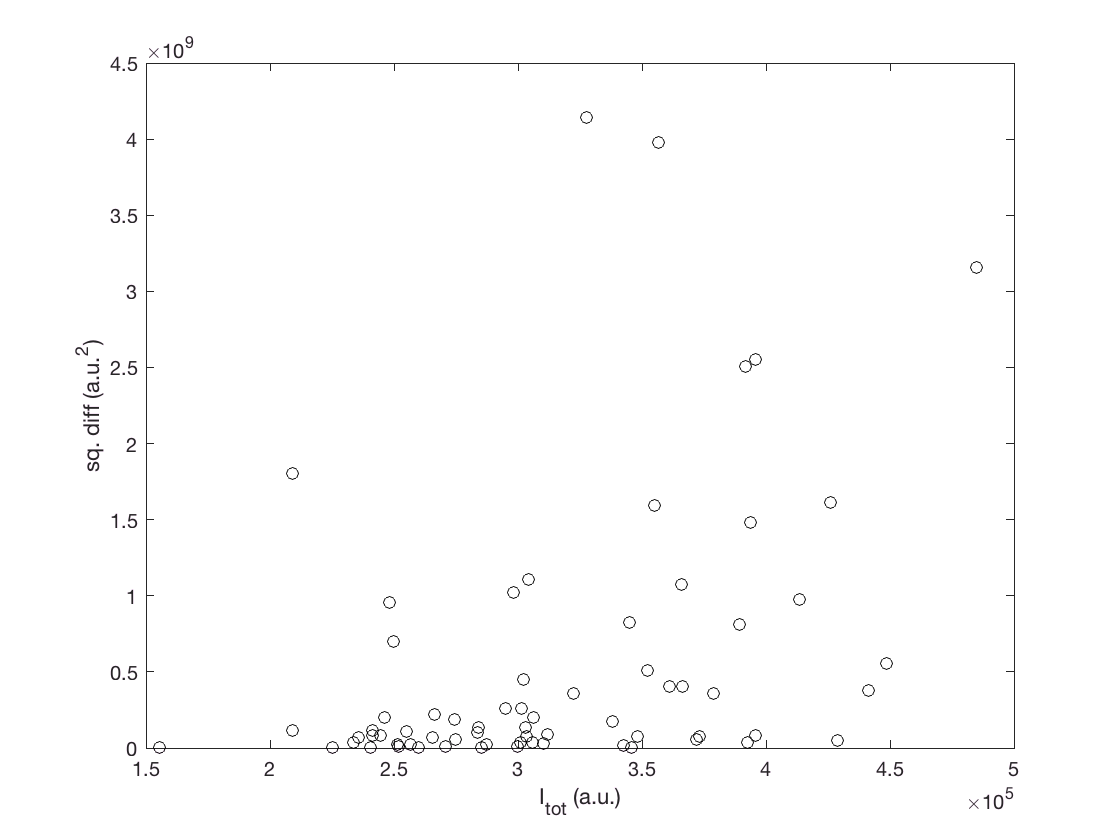

% Loop through each lineage file. 
matchedPairs = [];
cell1 = [];
cell2 = [];
for i=1:length(lineageFiles)
    cellStruct = load([dataDir lineageFiles{i}]);
    sisterID = cellStruct.sisterID;
    ownID = cellStruct.ID;
    % Loop through each ID.
    for j=1:length(cellId)
        if any(matchedPairs == ownID) || any(matchedPairs == sisterID);
           continue
        elseif cellId(j) == ownID
            continue
        elseif cellId(j) == sisterID
            sisterIndex = find(cellId == sisterID);
            ownIndex = find(cellId == ownID);
            cell1 = [cell1 intensity(ownIndex)];
            cell2 = [cell2 intensity(sisterIndex)];
            
            % Add the ID's of this round to the storage vector to make sure we
            % don't double up. 
            matchedPairs = [matchedPairs sisterID, ownID];
        end
    end
end
    

%Compute the squared difference. 
sqDiff = (cell1 - cell2).^2;
I_tot = (cell1 + cell2);

plot(I_tot, sqDiff, 'ko');
xlabel('I_{tot} (a.u.)');
ylabel('sq. diff (a.u.^2)');

That's not a lot of data points, but the overal trend is promising. It appears that the bulk of the points are relatively low in value with some wild outliers stretching to large values. Let's see if I can package this into a a minimal sensical loop and apply it ot the entire image that's been processed 

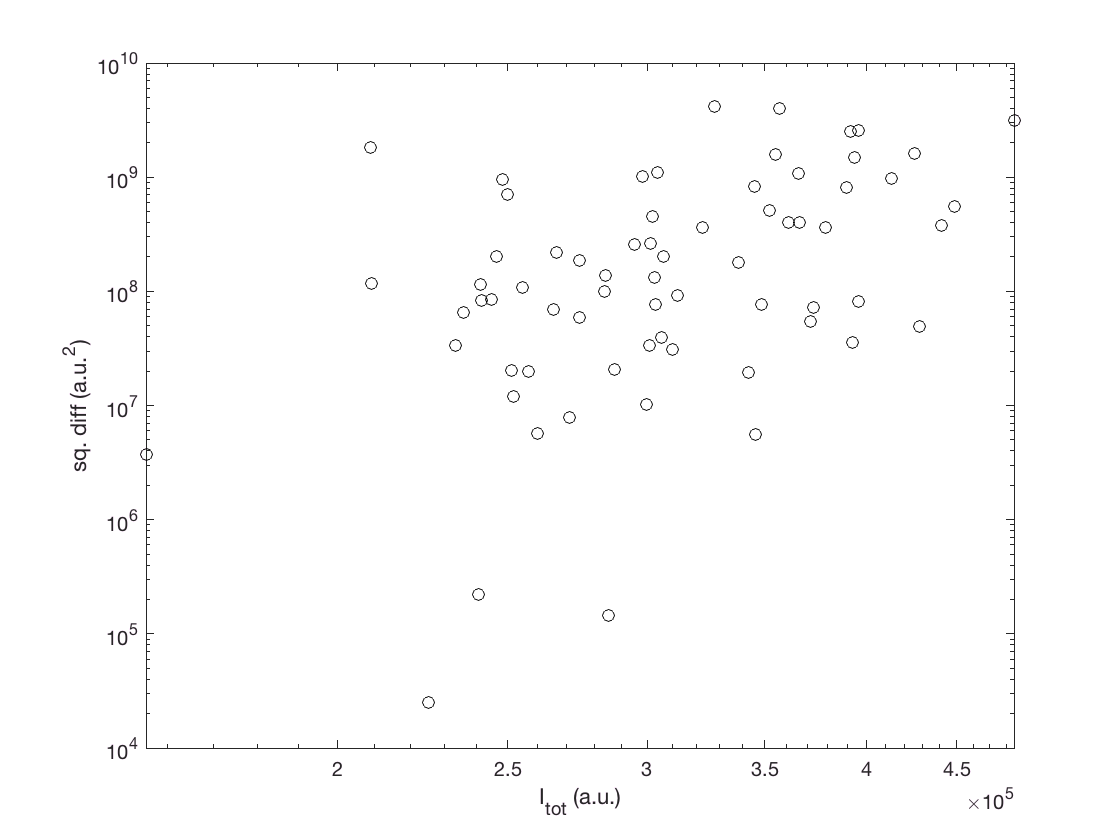

% Define the new data directory with the entire image processed.
dataDir = '../../data/mbl_2017/images/supersegger_practice/20170628_glucose_fullphase/xy3/cell/';

% Get the file names. 
files = dir([dataDir '*ell*.mat']);

% Load the fluorescence image. 
imFluo = imread('../../data/mbl_2017/images/supersegger_practice/20170628_glucose_fullfluo/growth_movie003t22xy03c3.tif');

% Loop through and load.
lineageFiles = {};
cellId = [];
intensity = [];
matchedPairs = [];
approvedCells = zeros(size(imFluo));
approvedCells = uint16(approvedCells);
counter = 0;
for i=1:length(files)
    % Load the structure and make sure it isn't born on frame 0 and dies on the final Frame. 
    cellStruct = load([dataDir files(i).name]);
    if (cellStruct.death == 22) && (cellStruct.birth ~= 1)
        counter = counter + 1;
        lineageFiles{counter} = files(i).name; 
        
        % Store the intensity values of each cell and the cell ID. 
        intensity(counter) = cellStruct.CellA{end}.fl2.sum;
        cellId(counter) = cellStruct.ID;
    end
end

% Now loop through all of the structs again to compute the pairings. 
cell1 = [];
cell2 = [];
for i=1:length(lineageFiles)
    cellStruct = load([dataDir lineageFiles{i}]);
    sisterID = cellStruct.sisterID;
    ownID = cellStruct.ID;
    % Loop through each ID.
    for j=1:length(cellId)
        if any(matchedPairs == ownID) || any(matchedPairs == sisterID);
           continue
        elseif cellId(j) == ownID
            continue
        elseif cellId(j) == sisterID
            sisterIndex = find(cellId == sisterID);
            ownIndex = find(cellId == ownID);
            cell1 = [cell1 intensity(ownIndex)];
            cell2 = [cell2 intensity(sisterIndex)];
            
            % Add the ID's of this round to the storage vector to make sure we
            % don't double up. 
            matchedPairs = [matchedPairs sisterID, ownID];
        end
    end
end
    

%Compute the squared difference. 
sqDiff = (cell1 - cell2).^2;
I_tot = (cell1 + cell2);

figure()
loglog(I_tot, sqDiff, 'ko');
xlabel('I_{tot} (a.u.)');
ylabel('sq. diff (a.u.^2)');

This seems very robust. Now I'll try to write all of this into a function that will take the following variables:

- The xy directory

- The mCherry channel name. 

- The length of the growth movie.

It will return the following the list of square differences and the intensity of the mother as two vectors.

z = dataDir(1:end-5)

dataDir = ../../data/mbl_2017/images/supersegger_practice/20170628_glucose_fullphase/xy3/cell/

dataDir = '../../data/mbl_2017/images/supersegger_practice/20170628_glucose_fullphase/xy3/';


z = ../../data/mbl_2017/images/supersegger_practice/20170628_glucose_fullp

   147



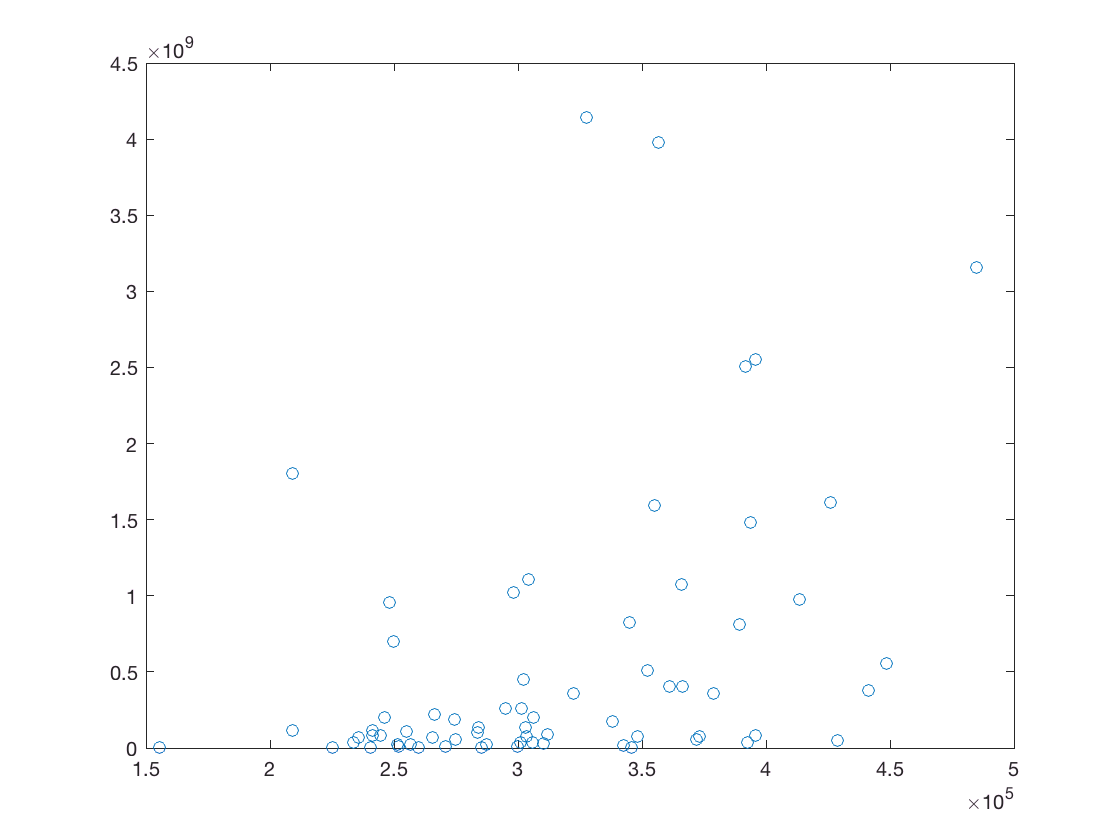

[a, b] = measuretriads(dataDir, 22);
plot(b, a, 'o')